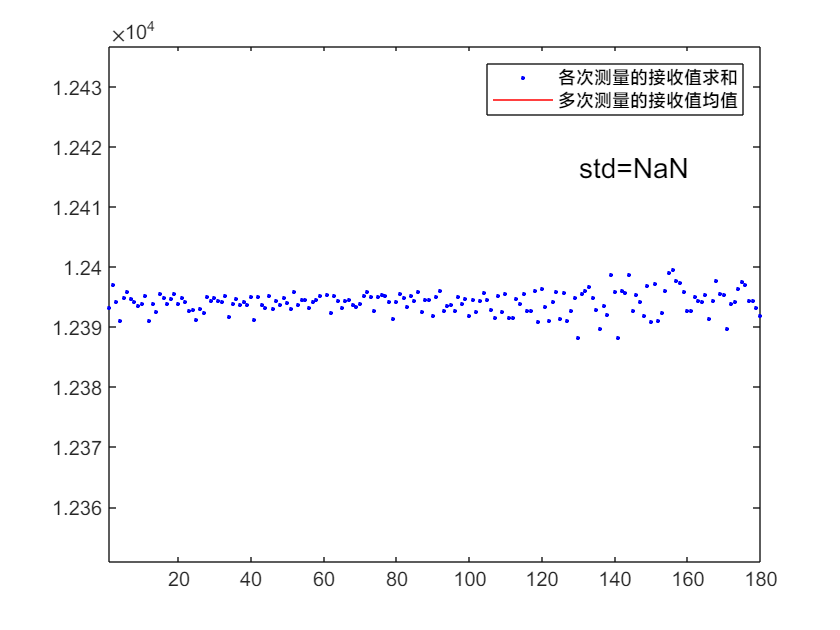

clc;close all;
%% 获取数据
dataFile = 'fujian.xls';
data = xlsread(dataFile,2);
%% 参数设定
lenTheta = 180;
% 总测量角度数
pixScale = 512;
% 单次测量像素数目
normScale= 100;
% 标准尺度(100mm)
graphScale=256;
% 目标像素尺度(256pixel)
a=40; b=15; R=4;
% 图形参数
normEllipsO = [50,50]; % 椭圆中心位置
normCircleO = [95,50]; % 圆形中心位置
%% 基本信息提取
figure('Name','各次测量的接收值总和');plot(sum(data),'b.');hold on;
axis([1,lenTheta,min(sum(data))*0.997,max(sum(data))*1.003]);
plot([1,lenTheta],[mean(sum(data)),mean(sum(data))],'r-');
text(lenTheta-50,max(sum(data))*1.003-20,['std=',num2str(std(sum(data)))],'FontSize',14);
legend('各次测量的接收值求和','多次测量的接收值均值');

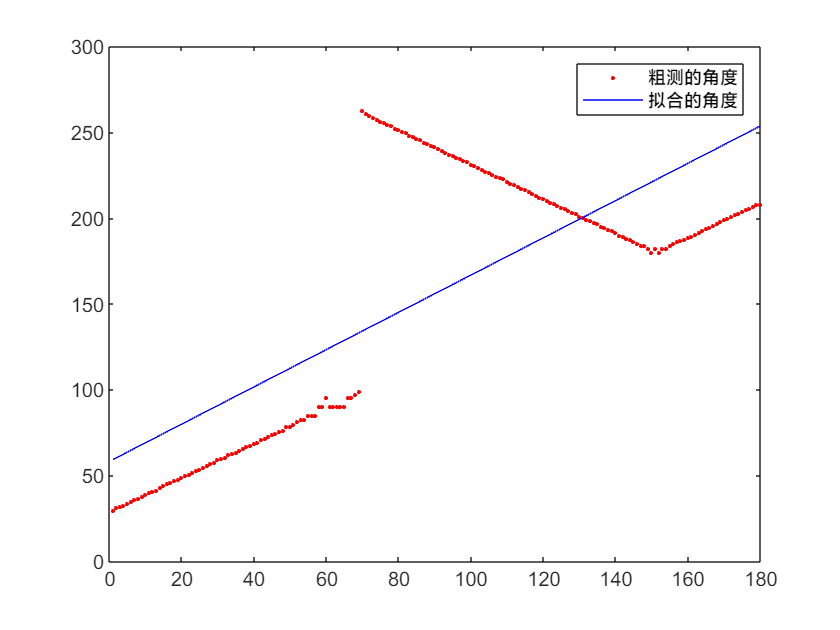

%% 粗测尺度及角度
% 获取曲线边缘，得到椭圆宽度变化
% figure(’Name’,’原始数据灰度图’);colormap(gray);imagesc(data);
curv = abs(diff(data));
curv = curv > 1;
se = strel('square',3);
curvEllips = imopen(curv,se);
curvEllips = bwareaopen(curvEllips,500);
% 得到每一角度对应的椭圆宽度数据
widthEllips = zeros(1,lenTheta);
for j=1:lenTheta
widthEllips(j) = find(curvEllips(:,j),1,'last')-(find(curvEllips(:,j),1,'first'));
end
% 粗略计算角度和尺度
roughScale = max(widthEllips)/2/a;
normWidthEllipse = widthEllips/roughScale;
roughTheta = zeros(1,lenTheta);
for j=1:lenTheta
roughTheta(j) = 180/pi*real(acot(sqrt((4*a^2-normWidthEllipse(j)^2)/(normWidthEllipse(j)^2-4*b^2))));
end
% 拟合得到各个角度,粗略得到逆变换图
diffRoughTheta = diff(roughTheta);
breakP1 = find(diffRoughTheta<-0.1,1);
breakP2 = find(diffRoughTheta(breakP1+10:end)>0.1,1)+breakP1+10;
roughTheta(1:breakP1)=roughTheta(1:breakP1);
roughTheta(breakP1+1:breakP2-1)=180-roughTheta(breakP1+1:breakP2-1);
roughTheta(breakP2:end)=180+roughTheta(breakP2:end);
[temp,~]=polyfit(1:lenTheta,roughTheta,1);
k_temp = temp(1);
b_temp = temp(2);
linerTheta = (1:lenTheta)*k_temp+b_temp;
figure('Name','粗测角度及拟合情况');plot(1:lenTheta,roughTheta,'r.');
hold on;plot(1:lenTheta,linerTheta,'b-');
legend('粗测的角度','拟合的角度');

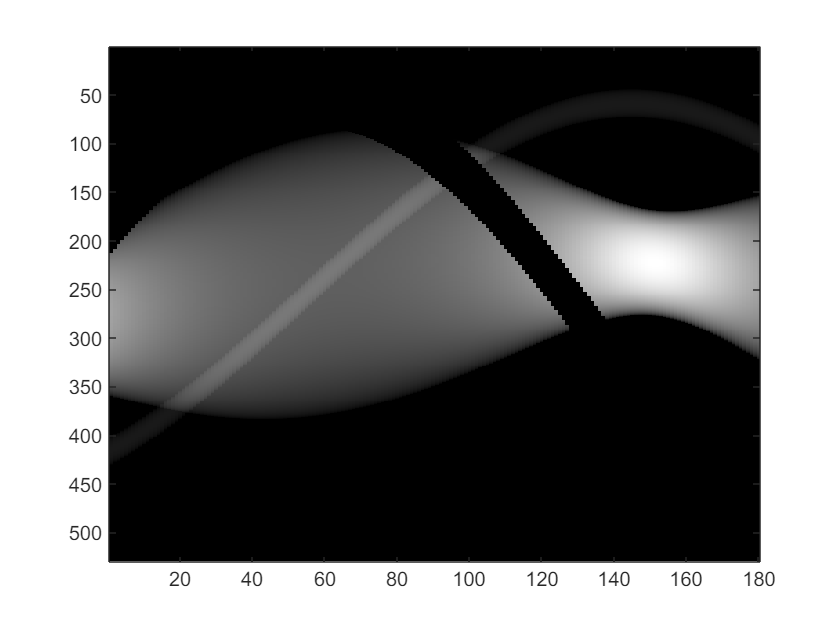

roughMap = iradon(data,linerTheta,pixScale);

% 旋转修正
Status = regionprops((roughMap>max(max(roughMap))/5));
[~,orderEllips] = max([Status(:).Area]);
[~,orderCircle] = min([Status(:).Area]);
pixEllipsO = Status(orderEllips).Centroid;
pixCircleO = Status(orderCircle).Centroid;
fixAng = angle((pixCircleO-pixEllipsO)*[1;1i]);
linerTheta = linerTheta+fixAng*180/pi;
roughMap = iradon(data,linerTheta,pixScale);
% 得到小圆圆心在图像中位置
Status = regionprops((roughMap>max(max(roughMap))/5));
[~,orderCircle] = min([Status(:).Area]);
pixCircleO = Status(orderCircle).Centroid;
pixO = [pixScale/2,pixScale/2];
% 得到轴在探测器阵列中的投影位置
[~,minWidthEllipsPos] = min(widthEllips);
tempStart = find(data(:,minWidthEllipsPos)>0,1,'first');
tempEnd = find(data(tempStart:end,minWidthEllipsPos)==0,1,'first')+tempStart;
AxisPosInSensors = (tempStart+tempEnd)/2+abs(pixO(1)-pixCircleO(1));
%% 拟合得到精确尺寸和角度
% 拟合准备
pixCircleCenter = zeros(1,lenTheta);
pixEllipsCenter = zeros(1,lenTheta);
fitEllipsData= data;
fitCircleData= data;
fitEllipsAns = zeros(pixScale,lenTheta);
fitCircleAns = zeros(pixScale,lenTheta);
fitAns = zeros(3,lenTheta);
fitMin = max(max(data))*0.01;
x = 1:pixScale;
% 拟合过程
for j=1:lenTheta
% 椭圆的宽度曲线拟合
pixCircleCenter(j) = int16(AxisPosInSensors - norm(pixO-pixCircleO)*cos(linerTheta(j)/180*pi+angle((pixO-pixCircleO)*[1;1i])));
fitEllipsData(int16(pixCircleCenter(j)-2*R*roughScale:pixCircleCenter(j)+2*R*roughScale),j)=0;
fitEllipsRange = find(fitEllipsData(:,j)>fitMin);
fitEllips = polyfit(x(fitEllipsRange)',fitEllipsData(fitEllipsRange,j).^2,2);
fitEllipsAns(:,j) = (fitEllips(1)*x.^2+fitEllips(2)*x+fitEllips(3))';
fitEllipsAns(fitEllipsAns(:,j)<0,j)=0;
fitEllipsAns(:,j) = sqrt(fitEllipsAns(:,j));
% 圆的宽度曲线拟合
fitCircleData(:,j) = data(:,j)-fitEllipsAns(:,j);
fitCircleRange = find(fitCircleData(:,j)>fitMin);
fitCircle = polyfit(x(fitCircleRange)',fitCircleData(fitCircleRange,j).^2,2);
fitCircle(2) = -fitCircle(2);
fitCircleAns(:,j) = (fitCircle(1)*x.^2+fitCircle(2)*x+fitCircle(3))';
fitCircleAns(fitCircleAns(:,j)<0,j)=0;
fitCircleAns(:,j) = sqrt(fitCircleAns(:,j));
% 拟合结果处理
pixCircleCenter(j) = -fitCircle(2)/fitCircle(1)/2;
pixEllipsCenter(j) = -fitEllips(2)/fitEllips(1)/2;
deltaL = 8/(sqrt(abs(fitCircle(2)^2-4*fitCircle(1)*fitCircle(3)))/abs(fitCircle(1)));
G = -8/((fitCircle(2)^2-4*fitCircle(1)*fitCircle(3))/fitCircle(1)/4);
temp = -deltaL^2*(fitEllips(3)-fitEllips(2)^2/fitEllips(1)/4)/fitEllips(1);
cosTheta2 = (temp/b^2-a^2/b^2)/(1-a^2/b^2);
fitAns(:,j) = [deltaL;G;cosTheta2];
% my fix
fitAns(3,:) = ones(1,180);
end
figure('Name','椭圆部分数据图');colormap(gray);imagesc(fitEllipsData);

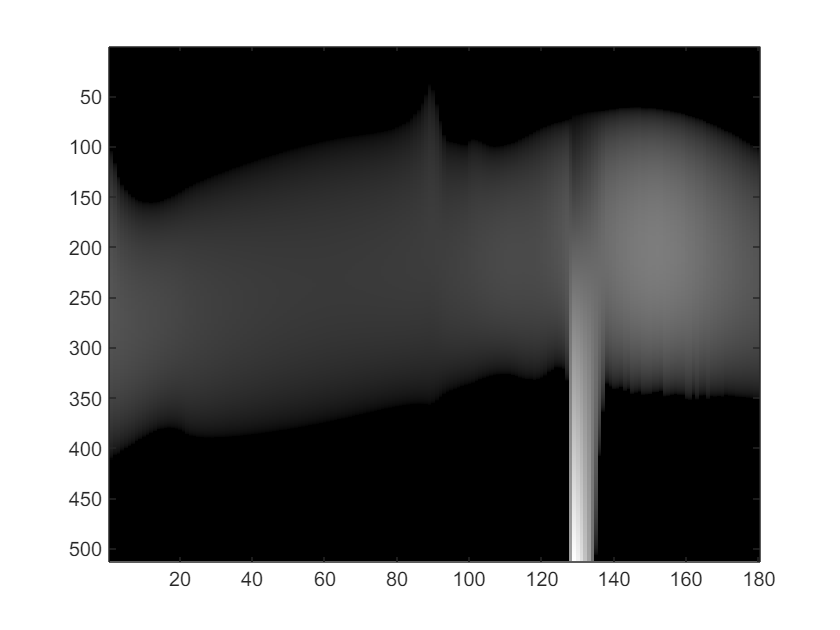

figure('Name','椭圆部分拟合图');colormap(gray);imagesc(fitEllipsAns);

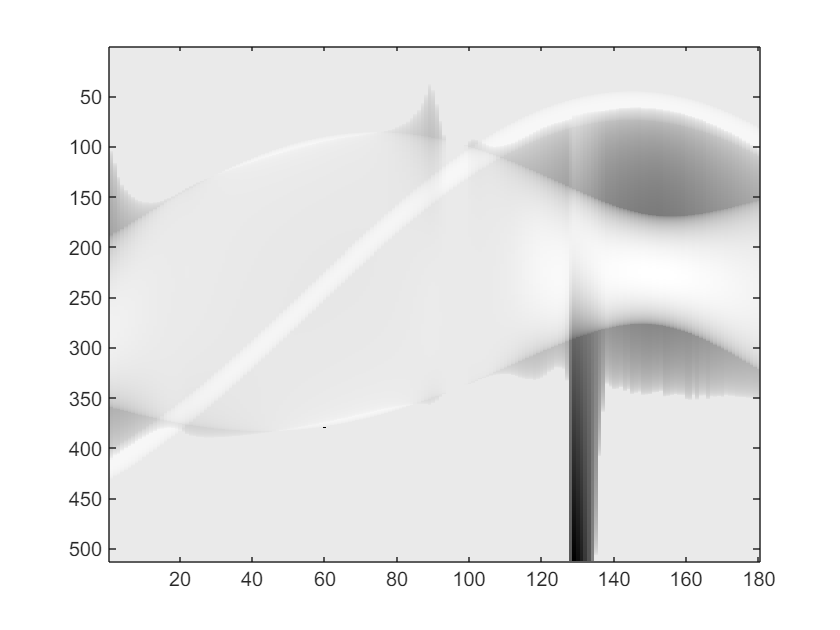

figure('Name','小圆部分数据图');colormap(gray);imagesc(fitCircleData);

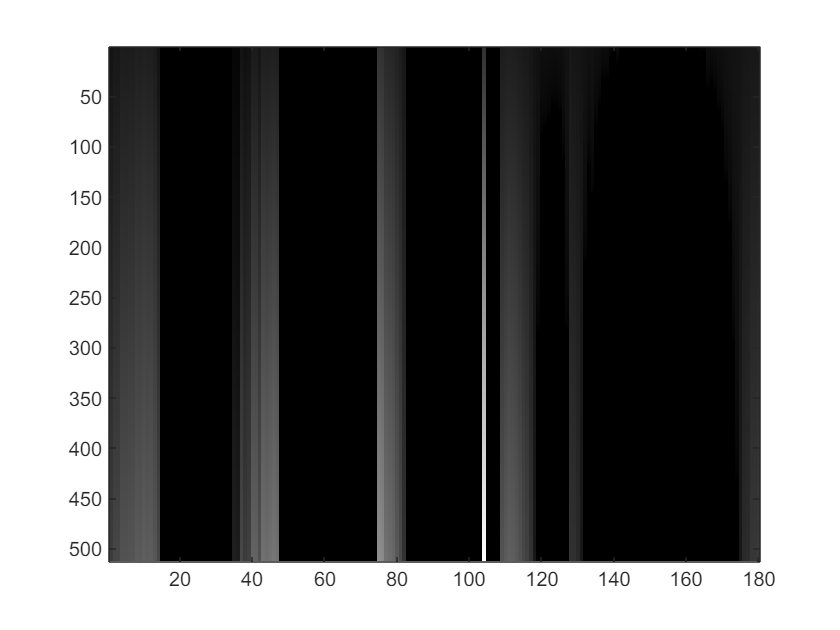

figure('Name','小圆部分拟合图');colormap(gray);imagesc(fitCircleAns);

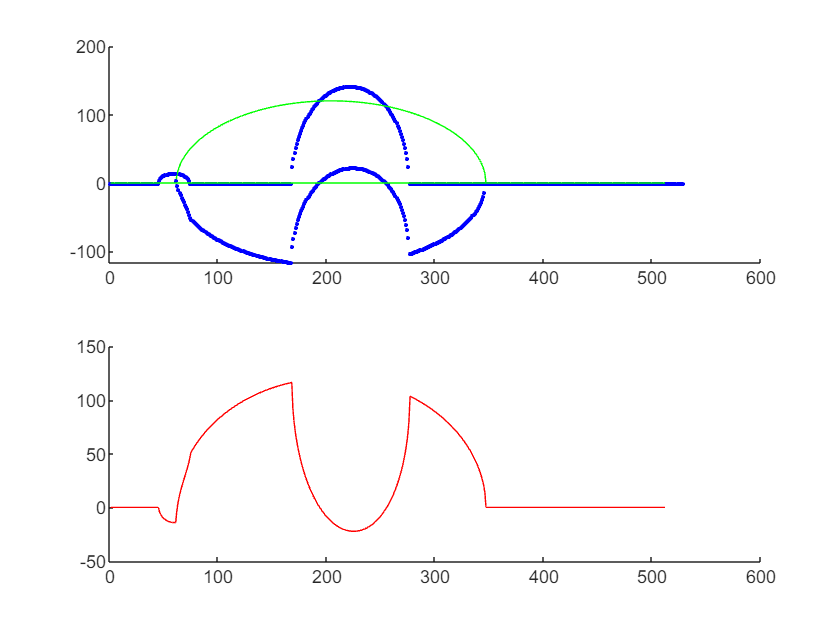

figure('Name','拟合结果与实际数据比对图');
temp = 150;
subplot(2,1,1);hold on;
plot(fitEllipsData(:,temp),'b.');plot(fitEllipsAns(:,temp),'g-');
plot(fitCircleData(:,temp),'b.');plot(fitCircleAns(:,temp),'g-');
subplot(2,1,2);hold on;
%plot(fitEllipsAns(:,temp)-fitEllipsData(:,temp),'r-');
plot(fitCircleAns(:,temp)-fitCircleData(:,temp),'r-');

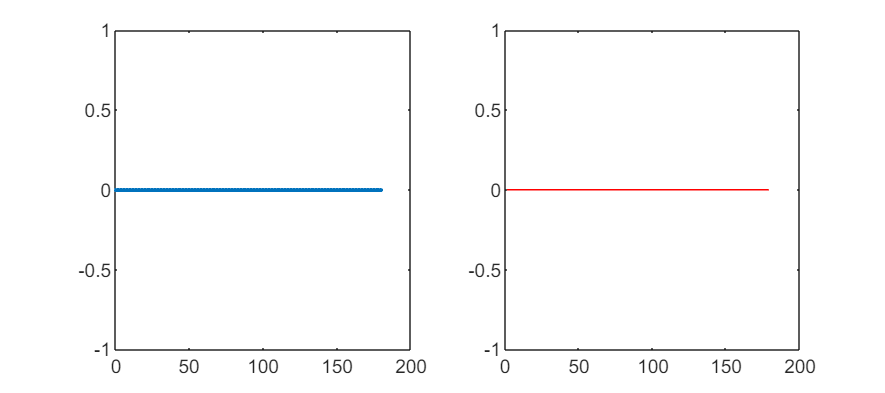

% 得到拟合出的角度并修正方向
fixTheta = 1/2*acos(2.*fitAns(3,:)-1)*180/pi;
diffFixTheta = diff(fixTheta);
breakP1 = find(diffFixTheta<0,1);
breakP2 = find(diffFixTheta(breakP1+1:end)>0,1)+breakP1+1;
fixTheta(1:breakP1)=fixTheta(1:breakP1);
fixTheta(breakP1+1:breakP2-1)=180-fixTheta(breakP1+1:breakP2-1);
fixTheta(breakP2:end)=180+fixTheta(breakP2:end);
figure('Name','修正后的各个角度');subplot(1,2,1);plot(fixTheta,'.');
subplot(1,2,2);plot(diff(fixTheta),'r-');
set(gcf,'Position',[500 500 900 400]);

%% 相关参数的求解
% 得到深度系数和探测器间距
G = mean(fitAns(2,:));
deltaL = mean(fitAns(1,:));
[interpData,intepTheta]=interpForIradon(fixTheta,data);

索引超过数组元素的数量。索引不能超过 0。

出错 A1From02>interpForIradon (第 203 行)
        if interpTheta(j)<Theta(j)

fixMap = iradon(interpData,intepTheta,'spline','Hann',pixScale);
% 精测旋转中心
Status = regionprops((fixMap>max(max(fixMap))/5));
[~,orderEllips] = max([Status(:).Area]);
[~,orderCircle] = min([Status(:).Area]);
pixEllipsO = Status(orderEllips).Centroid;
pixCircleO = Status(orderCircle).Centroid;
pixO = [pixScale/2,pixScale/2];
normO = ((2*pixO-pixEllipsO-pixCircleO)*deltaL+normEllipsO+normCircleO)/2;
figure('Name','修正的重建图像');colormap(gray);imshow(fixMap);
hold on;plot(pixO(1),pixO(2),'ro');
plot([pixEllipsO(1),pixCircleO(1)],[pixEllipsO(2),pixCircleO(2)],'ko');
plot([pixO(1),pixEllipsO(1),pixCircleO(1),pixO(1)],[pixO(2),pixEllipsO(2),pixCircleO(2),pixO(2)],'b-')
% 绘制原尺寸图内的旋转中心
figure('Name','旋转中心示意图');
plot([0,100,100,0],[0,0,100,100],'k-');hold on;
tempLen = 1000;
xEllipsPos = zeros(tempLen);
yEllipsPos = zeros(tempLen);
xCirclePos = zeros(tempLen);
yCirclePos = zeros(tempLen);
for i=1:tempLen
sita = i/tempLen*2*pi;
xEllipsPos(i) = b*cos(sita)+normEllipsO(1);
yEllipsPos(i) = a*sin(sita)+normEllipsO(2);
xCirclePos(i) = R*cos(sita)+normCircleO(1);
yCirclePos(i) = R*sin(sita)+normCircleO(2);
end
plot(xEllipsPos,yEllipsPos,'k-');
plot(xCirclePos,yCirclePos,'k-');
plot(normO(1),normO(2),'ro');
plot([normEllipsO(1),normCircleO(1)],[normEllipsO(2),normCircleO(2)],'ko');
plot([normO(1),normEllipsO(1),normCircleO(1),normO(1)],[normO(2),normEllipsO(2),normCircleO(2),normO(2)],'b-');
axis('equal');
set(gca,'YDir','reverse');
% 求解’吸收率’系数
figure('Name','重建图形的吸收率分布');hist(fixMap(:),1000);
[fixKm,fixKmC] = kmeans(fixMap(:),2);
Gt = max(fixKmC)/1.00;
%% 保存数据
CalibrationResults = {
{'Theta'; roundn(fixTheta,-4)};
{'normO'; roundn(normO,-4)};
{'deltaL';roundn(deltaL,-4)};
{'G';roundn(G,-4)};
{'Gt';roundn(Gt,-4)}
};
for i=1:length(CalibrationResults)
xlswrite('Calibration.xls',{CalibrationResults{i}{1}},1,['A' num2str(i)]);
xlswrite('Calibration.xls', CalibrationResults{i}{2} ,1,['B' num2str(i)]);
end


function [interpData,interpTheta]=interpForIradon(Theta,data)
    interpTheta = Theta(1):(Theta(end)-Theta(1))/(length(Theta)-1):Theta(end);
    interpData = data;
    for j=2:length(Theta)-1
        if interpTheta(j)<Theta(j)
            start = j-1; finish = j;
        else
            start = j; finish = j+1;
        end
        interpData(:,j) = (data(:,finish)-data(:,start))*...
            (interpTheta(j)-Theta(start))/(Theta(finish)-...
            Theta(start))+...
            data(:,start);
    end
end